使用**内置粒子群算法**对FOPID的参数进行调节。

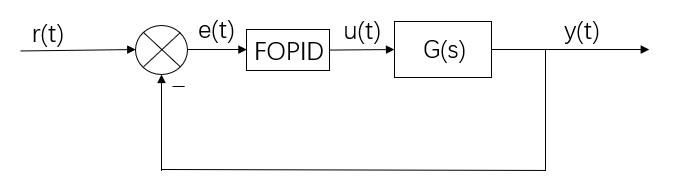

闭环控制

误差e=y-r，计算均方误差mse作为粒子的适应度。

clc
clear
close all

% 定义被控系统
global Wn zeta
Wn = 1;         % 固有频率 1rad/s
zeta = 0.5;     % 欠阻尼
Num = [Wn^2];
Den = [1, 2*zeta*Wn, Wn^2]; 

sys = tf(Num, Den)

sys =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



pole(sys)       % 系统有两个具有负实部的极点，系统稳定

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


% 生成参考信号
global tau T X0 h t r
tau = 10;
Tmax = 50;
X0 = [0;0];
h = 0.01;
T = 0:h:Tmax;
[r,t] = gensig('square',tau, Tmax, h);  % 参考信号

% 内置粒子群算法
N = 5;  % 例子维度
lb = [0; 0; 0; 0; 0];
ub = [5; 5; 5; 1; 1];
options = optimoptions('particleswarm','SwarmSize',20,'MaxIterations',20,'HybridFcn',@fmincon, 'Display', 'iter');

[x,fval,exitflag,output] = particleswarm(@calculate, N, lb, ub, options);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              20         0.02544         0.06109        0
    1              40         0.02056          0.1166        0
    2              60         0.02056         0.05954        1
    3              80         0.02055         0.02756        0
    4             100         0.02016         0.02549        0
    5             120         0.01933           0.024        0
    6             140          0.0193         0.02352        0
    7             160         0.01911          0.0215        0


fprintf('最终最优参数：');

最终最优参数：

disp(x)

    4.9998    4.9998    4.9999    0.5089    1.6999



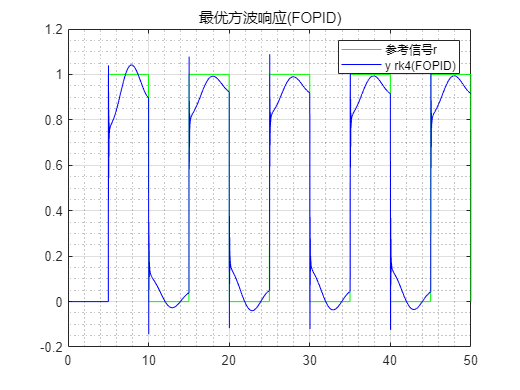

% FOPID控制
Kp = x(1);
Ki = x(2);
Kd = x(3);
lammda = x(4);
mu = x(5);
L = 10;  % fopid的记忆长度 单位：s

global sum_e e_last
sum_e = 0;     
e_last = 0;

%%%%%%%% 使用龙格库塔法求解系统响应 %%%%%%%%
N = length(T);
X = zeros(length(X0), N);
X(:, 1)=X0;
err = zeros(length(X0), N);
input = zeros(length(X0),1);
for i =2:N        
    X_k = X(:,i-1);
    t_k = T(i-1);
    
    if mod(t_k, tau) <=5
        ref = 0;
    else
        ref = 1;
    end

    err(:, i) = ref - X_k;
%     if abs(ref - X_k)/ref > 2.0 % 超调过大视为不稳定
%         disp('系统不稳定');
%         break;
%     end
    u = fopid(err(1,:), Kp, Ki, Kd, lammda, mu, h, L/h, i);    % 只控制状态量X1
    input(i) = u;

    K1=fnc(t_k,X_k, u);
    K2=fnc(t_k+h/2,X_k+h/2*K1, u);
    K3=fnc(t_k+h/2,X_k+h/2*K2, u);
    K4=fnc(t_k+h,X_k+h*K3, u);
    
    X(:,i)=X_k + h/6*(K1+2*K2+2*K3+K4);
end


figure()
plot(t, r, 'g', T, X(1, :), 'b') % X(1,:)为系统的输出
title("最优方波响应(FOPID)")
legend("参考信号r","y rk4(FOPID)")
grid on
grid minor

粒子群算法寻参效果不佳，猜测是因为陷入了局部最优，想到一个解决办法：先从理论上整定控制器参数，然后将这个参数的小领域设为粒子群的搜索范围。

function mse = calculate(x)
    % 初始化FOPID
    Kp = x(1);
    Ki = x(2);
    Kd = x(3);
    lammda = x(4);
    mu = x(5);
    L = 10;

    global sum_e e_last tau T X0 h r
    sum_e = 0;     
    e_last = 0;
    
    %%%%%%%% 使用龙格库塔法求解系统响应 %%%%%%%%
    N=length(T);
    X=zeros(length(X0),N);
    X(:,1)=X0;
    err = zeros(length(X0), N);
    input = zeros(length(X0),1);
    for i =2:N        
        X_k = X(:,i-1);
        t_k = T(i-1);
        
        if mod(t_k, tau) <=5
            ref = 0;
        else
            ref = 1;
        end
        
        err(:, i) = ref - X_k;
%         if abs(ref - X_k)/ref > 2.0 % 超调过大视为不稳定
%             disp('系统不稳定');
% %             X=inf*ones(length(X0),N);
%             break;
%         end
        u = fopid(err(1,:), Kp, Ki, Kd, lammda, mu, h, L/h, i);    % 只控制状态量X1
        input(i) = u;

        K1=fnc(t_k,X_k, u);
        K2=fnc(t_k+h/2,X_k+h/2*K1, u);
        K3=fnc(t_k+h/2,X_k+h/2*K2, u);
        K4=fnc(t_k+h,X_k+h*K3, u);
        
        X(:,i)=X_k + h/6*(K1+2*K2+2*K3+K4);
    end
    
    output = X(1,:)';
    e = r - output;
    % 均方误差
    mse = sum(e.^2)/length(e);
    % 平均误差
%     e = abs(e);
%     mse = sum(e)/length(e);
end
    
function dx = fnc(t, x, u)
    global Wn zeta
    dx = zeros(length(x), 1);
    dx(1) = x(2);
    dx(2) = -Wn^2*x(1) - 2*zeta*Wn*x(2) + Wn^2*u;
end
